**Data**

x1 = [0 1 1 2 2 3 3 4 4]';
x2 = [0 1 2 1 2 1 2 1 2]';
y = [15.1 17.9 12.7 25.6 20.5 35.1 29.7 45.4 40.2]';

**Plot data**

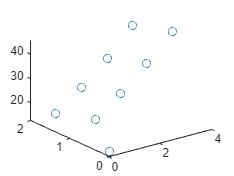

plot3(x1,x2,y,'o')

**Create Z matrix**

z = [ones(9,1) x1 x2]

z =      1     0     0
     1     1     1
     1     1     2
     1     2     1
     1     2     2
     1     3     1
     1     3     2
     1     4     1
     1     4     2


**Solve for unknown parameters  a  **

a = (z'*z) \ (z'*y)

a =    14.4609
    9.0252
   -5.7043


**Plot data and the best fitted curve**

xx1 = 0 : 0.2 : 4

xx1 =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


xx2 = 0 : 0.1 : 2

xx2 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000



yy = a(1) + a(2).*xx1 + a(3).*xx2

yy =    14.4609   15.6955   16.9301   18.1647   19.3993   20.6339   21.8685   23.1031   24.3377   25.5723   26.8070   28.0416   29.2762   30.5108   31.7454   32.9800   34.2146   35.4492   36.6838   37.9184   39.1530


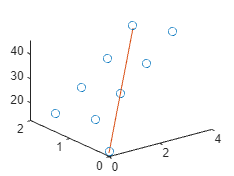


plot3(x1,x2,y,'o',xx1,xx2,yy,'-')

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

Sr = sum((y-z*a).^2)

Sr = 4.7397

**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

St = sum((y-mean(y)).^2)

St = 1.0587e+03

**Compute  r2  (the coefficient of determination)**

r2 = 1 - Sr/St

r2 = 0.9955

**Compute  syx  (the standard error of the estimate)  **

syx = sqrt(Sr/(length(x)-length(a)))

syx = 0.9736

**Predict the value of y for the given x**

xtest1 = 3;
xtest2 = 3;
predict_y = a(1) + a(2).*xtest1 + a(3).*xtest2

predict_y = 24.4235